***Wireless Communications EL-GY 6023***

Homework 5 - Tommy Azzino (ta1731)

Problem 2

Problem 6    

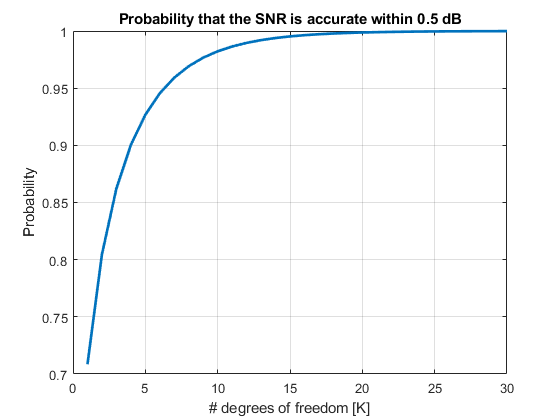

num_ks = 30;
k = 1:num_ks;
true_avgSnr_db = 3;
true_avgSnr = db2pow(true_avgSnr_db);
target_db = 0.5;
target = db2pow(target_db);
alpha = target + true_avgSnr + 1;
prob_v = fcdf(alpha, k, k);

figure;
plot(k, prob_v, "LineWidth",2); grid on;
xlabel("# degrees of freedom [K]");
ylabel("Probability");
title("Probability that the SNR is accurate within 0.5 dB");

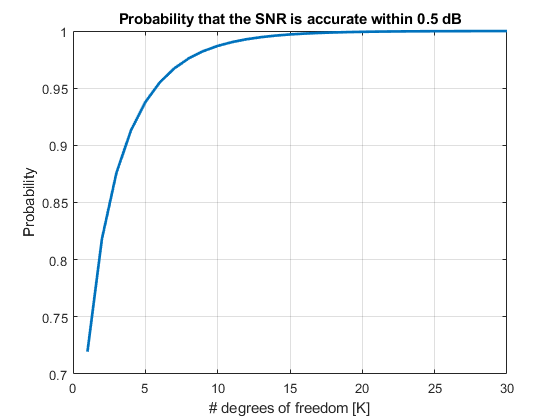


prob_v = fcdf(target_db+true_avgSnr_db+1, k, k);
figure;
plot(k, prob_v, "LineWidth",2); grid on;
xlabel("# degrees of freedom [K]");
ylabel("Probability");
title("Probability that the SNR is accurate within 0.5 dB");

As we can see from the figure above, as we increase the number of degrees of freedom (i.e. the number of symbols we use to estimate the SNR), the probability of having an estimation accuracy within 0.5 dB increases